clear all
d1=load("precipitation\PPT_zscore.mat");
d2=load("Soil moisture\SM_zscore.mat");
d3=load("L band VOD\VOD_zscore.mat");
d4=load("SIF data\SIF_zscore.mat");
d5=load("SPI weekly\SPI_1month_08_18.mat");
d6=load("VODCA VOD\VOD_X_zscore.mat");
d7=load("VODCA VOD\VOD_C_zscore.mat");


ppt=d1.Z(:,:,1:132);
sm=d2.Z(:,:,1:132);
vod=d3.Z(:,:,1:132);
sif=d4.Z(:,:,1:132);
spi=d5.SPI(:,:,1:132);
vod_x=d6.Z(:,:,1:132);
vod_c=d7.Z(:,:,1:132);

d=201711;

for p=1:132
    if spi(1,1,p)==d
        i=p;
        break
    end
end

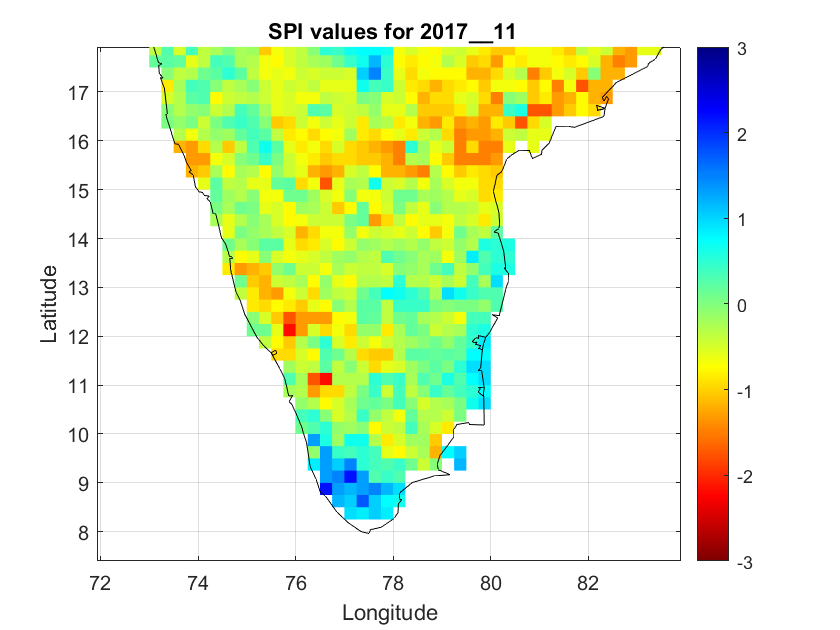

%spi
data=spi(:,:,i);
date=spi(1,1,i);
month=rem(date,100);
year=floor(date/100);
st_date=int2str(year)+"__"+int2str(month);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
f=figure(1);
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis
ylabel('Latitude'); % Labelling y axis
title(' SPI values for '+st_date); % Putting title to the figure
colormap(flipud(jet)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
caxis([-3 3])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
% saveas(f,"E:\MTP2\images\spi spatial plots\"+st_date+".png");
% clear figure(1);
% clear f;
% close;
xlim([71.95 83.90])
ylim([7.40 17.92])
hold off

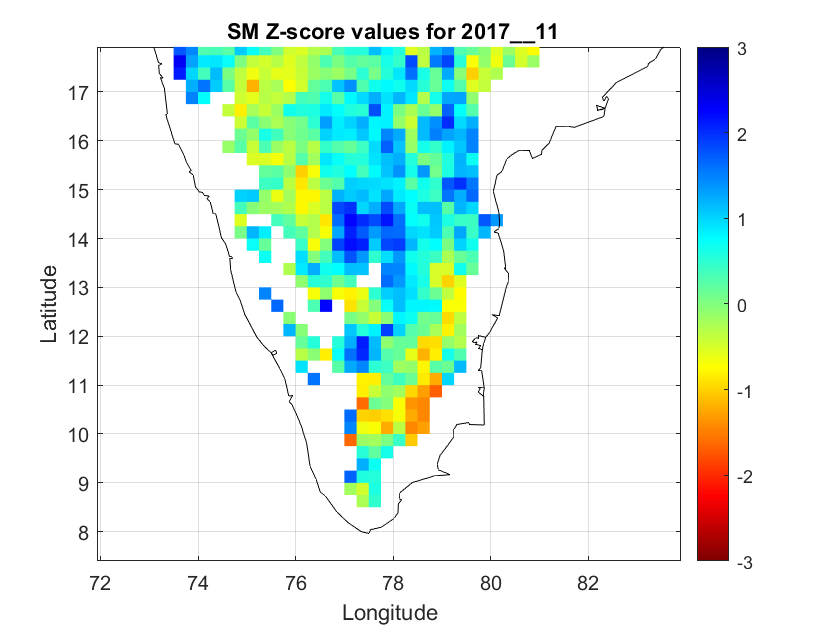

data=sm(:,:,i);
date=sm(1,1,i);
month=rem(date,100);
year=floor(date/100);
st_date=int2str(year)+"__"+int2str(month);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
f2=figure(2);
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis
ylabel('Latitude'); % Labelling y axis
title(' SM Z-score values for '+st_date); % Putting title to the figure
colormap(flipud(jet)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
caxis([-3 3])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); 
xlim([71.95 83.90])
ylim([7.40 17.92])
hold off

% data=vod(:,:,i);
% date=vod(1,1,i);
% month=rem(date,100);
% year=floor(date/100);
% st_date=int2str(year)+"__"+int2str(month);
% lat=data(2:130,1,1);
% lon=data(1,2:136,1)';
% crop1=(data(2:130,2:136,1));
% f3=figure(3);
% slp=pcolor(lon,lat,crop1);
% slp.EdgeColor='none';
% xlabel('Longitude'); % Labelling x axis
% ylabel('Latitude'); % Labelling y axis
% title(' VOD Z-score values for '+st_date); % Putting title to the figure
% colormap(flipud(jet)) % Setting a color scheme
% hcb1=colorbar; % Showing the scheme on a scale
% caxis([-3 3])
% %title(hcb1,'(in m3/m3)') % Titling a colorbar
% grid on % Showing grid lines
% hold on % Starting a new plot on same figure retaining the former
% geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0);
% hold off

% data=vod_c(:,:,i);
% date=vod_c(1,1,i);
% month=rem(date,100);
% year=floor(date/100);
% st_date=int2str(year)+"__"+int2str(month);
% lat=data(2:130,1,1);
% lon=data(1,2:136,1)';
% crop1=(data(2:130,2:136,1));
% f10=figure(10);
% slp=pcolor(lon,lat,crop1);
% slp.EdgeColor='none';
% xlabel('Longitude'); % Labelling x axis
% ylabel('Latitude'); % Labelling y axis
% title(' VOD_C Z-score values for '+st_date); % Putting title to the figure
% colormap(flipud(jet)) % Setting a color scheme
% hcb1=colorbar; % Showing the scheme on a scale
% caxis([-3 3])
% %title(hcb1,'(in m3/m3)') % Titling a colorbar
% grid on % Showing grid lines
% hold on % Starting a new plot on same figure retaining the former
% geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0);
% hold off

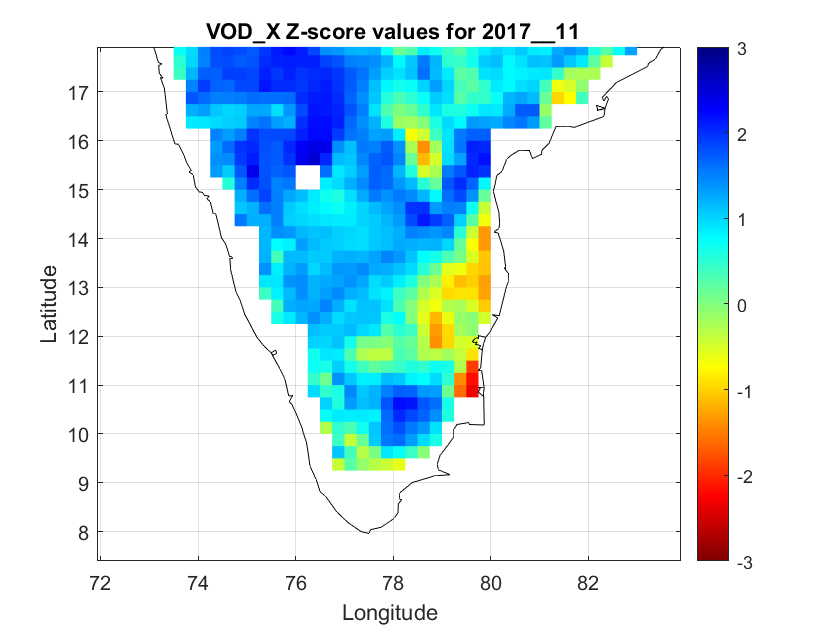

data=vod_x(:,:,i);
date=vod_x(1,1,i);
month=rem(date,100);
year=floor(date/100);
st_date=int2str(year)+"__"+int2str(month);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
f8=figure(8);
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis
ylabel('Latitude'); % Labelling y axis
title(' VOD_X Z-score values for '+st_date); % Putting title to the figure
colormap(flipud(jet)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
caxis([-3 3])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0);
xlim([71.95 83.90])
ylim([7.40 17.92])
hold off

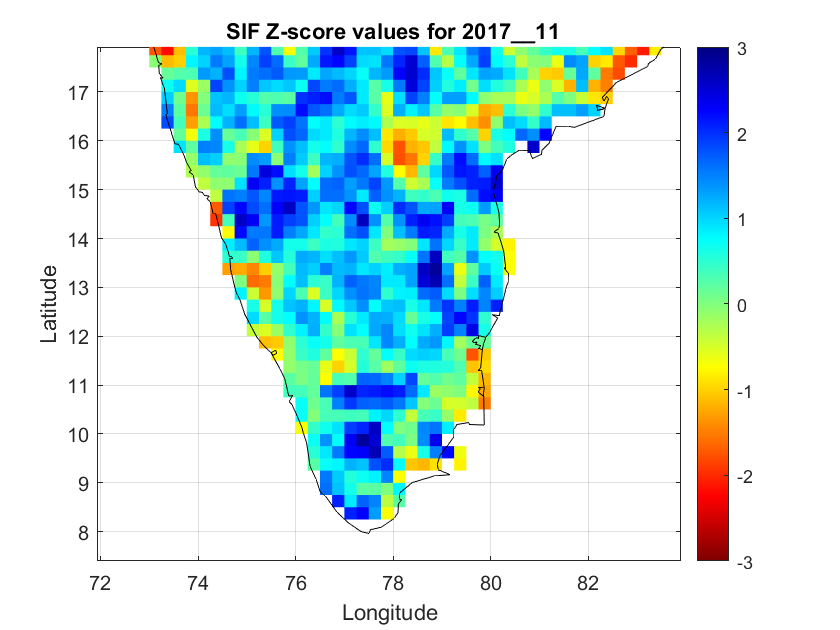

data=sif(:,:,i);
date=sif(1,1,i);
month=rem(date,100);
year=floor(date/100);
st_date=int2str(year)+"__"+int2str(month);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
f4=figure(4);
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis
ylabel('Latitude'); % Labelling y axis
title(' SIF Z-score values for '+st_date); % Putting title to the figure
colormap(flipud(jet)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
caxis([-3 3])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0);
xlim([71.95 83.90])
ylim([7.40 17.92])
hold off